# **Modeling and Simulation of Trumpet Electro-mechanic Horn**

**2022**

**Vibration and Acoustic Transducers Laboratry**

**Pohang University of Science and Technology**

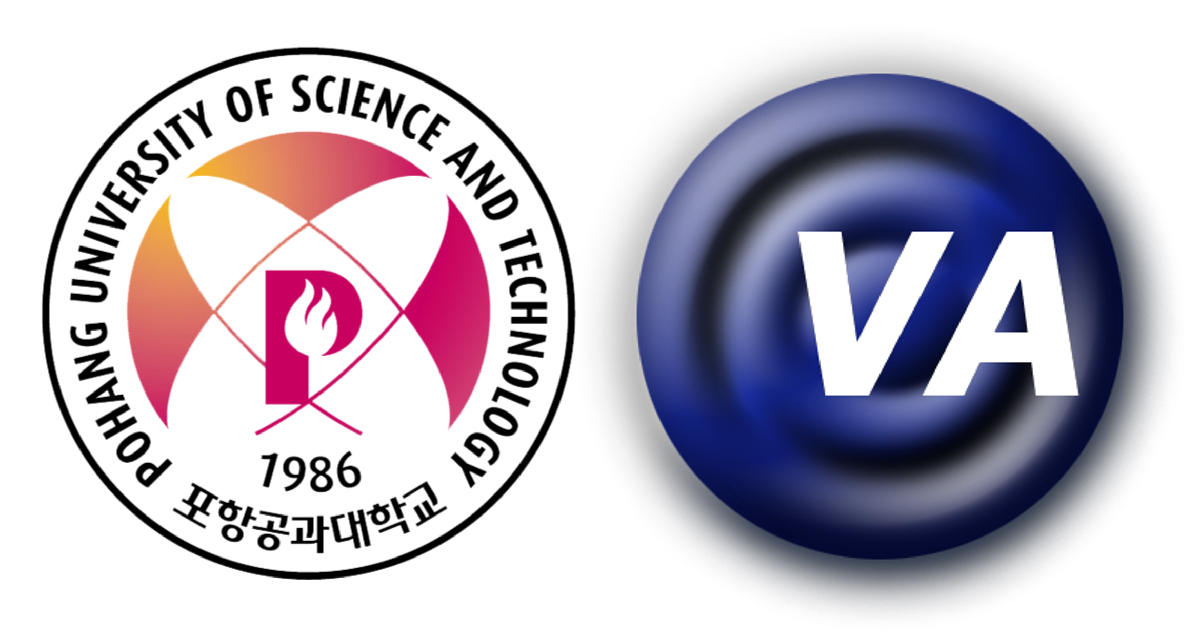

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

## **All(electro-mechano-acoustical) coupled -  time dependent - 3 DOF linear driver model**

## **Operating voltage sweep - Series computing**

### **Silmulation environment setup**

clear
proj = currentProject;
env.geom_str= "Geom_Horn.txt";  % Select geometry
env.mdl_str = 'All_Overall_time_dependent_3DOF_linear_driver_EMM';  % Select model
env.sweep   = 9:10;                  % Voltage parameters   
env.stdyt   = 0.2;                   % Set the time to enter steady state
env.stopt   = 0.4;                   % Simulation stop time

## **Acoustical components**

### Import geometry from text file

opts = delimitedTextImportOptions("NumVariables", 2);
% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = "\t";
% Specify column names and types
opts.VariableNames = ["Location", "Area"];
opts.VariableTypes = ["double", "double"];
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
% Import the data
Geom_Horn = readtable(env.geom_str, opts);
clear opts

### Physical properties of air

air.rho0    = 1.21; % Density,                  [kg/m^3]
air.c       = 343;  % Speed,                    [m/s]
air.gamma   = 1.402;% Ratio of specific heat,   [1]
air.p_ref   = 20e-6;% Reference for sound pressure level,   [Pa]

### Parallel section

ac.ps.x     = Geom_Horn.Location(2);                % Length
ac.ps.s     = Geom_Horn.Area(2);                    % Area
ac.ps.n     = 20;                                   % No. of subsection

ac.ps.L     = air.rho0/ac.ps.s*(ac.ps.x/ac.ps.n);   % L in T network of subsection
ac.ps.C     = ac.ps.s/(air.rho0*air.c^2)*(ac.ps.x/ac.ps.n);
                                                    % C in T network of subsection

### Horn

ac.ho.x     = Geom_Horn.Location(3:end)-Geom_Horn.Location(2:end-1);
                                                    % Length of subsection
ac.ho.s     = Geom_Horn.Area(3:end);                % Area of subsection
ac.ho.n     = size(ac.ho.x);                        % No. of subsection

ac.ho.L     = air.rho0./ac.ho.s.*ac.ho.x/2;         % L in T network of subsection
ac.ho.C     = ac.ho.s/(air.rho0*air.c^2).*ac.ho.x;  % C in T network of subsection

### Radiation

ac.rad.s    = Geom_Horn.Area(end);
ac.rad.a    = sqrt(ac.rad.s/pi);

### Compressor

ac.co.L     = 38361.196102405345/(2*pi*100);
ac.co.C     = 1/(2*pi*100*4.518859697974938e7);

## **Mechanical components**

### Diaphragm modeled by 3DOF linear

me.di.R    = 1;                     % Damping coefficient,  [N.s/m]

%% for 3DOF linear driver
me.dl.f    = [347.8491105695766 4002.8759129004957 9118.609276012086];
me.dl.phi  = [37.47048679642662 2.4855617498927827 1.8325667984395029];

%% Spring swtich from the experiment result (FD curve of spring)
me.sw.K_pt  = 31e3;                 % Pretensioned-spring coefficients, [N/m]
me.sw.K     = 7e3;                  % Spring coefficients,  [N/m]

### Diaphragm modeled by 1DOF nonlinear

%% for 1DOF non-linear driver
me.dn.M     = 0.028596625123380574; % Mass,                         [kg]
me.dn.Kt    = [1.028e+05    1.674e+08   2.022e+05   0   0];
                                    % Positive spring coefficients, [N/m]
me.dn.Kc    = [6.466e+04    0   0   0   0];
                                    % Negative spring coefficients, [N/m]

## **Mechano-acoustical coupling**

### Diaphragm

ma.di.s    = 0.0036417751495247705;
ma.di.psi  = [0.49105789017885293	4.641306076294213	0.008159872921131028];

## **Electrical components**

### Coil

el.coil.Ls  = 800e-6;       % Coil series inductance,       [H]
el.coil.Rs  = 670e-3;       % Coil series resistance,       [Ohm]
el.coil.Rs1 = 000e-3;       % Additional series resistance, [Ohm]
el.coil.N   = 140;          % No. of winding turns,         [1]

### Power Supply

el.ps.V     = 12;           % Power supply voltage,         [V]

### Switch

el.sw.R_on  = 1e-3;         % On state switch resistance,   [Ohm]
el.sw.R_off = 1e7;          % Off state switch resistance,  [Ohm]

## **Magnetic components**

ma.arm.r    = 5.1e-3;       % Armature radius               [m]

## **Magneto-mechanical coupling**

mm.gap      = 1.2e-3;       % Gap distance between armature and pole,   [m]

## **Electro-mechanical coupling**

### Spring swtich

em.sw.x_on_pt   = -70e-6;   % Transition position from spring switch free to pretensioned,  [m]
em.sw.x_off     = -360e-6;  % Transition position from spring switch pretensioned to off,   [m]

## **Operating voltage sweep - Series computing**

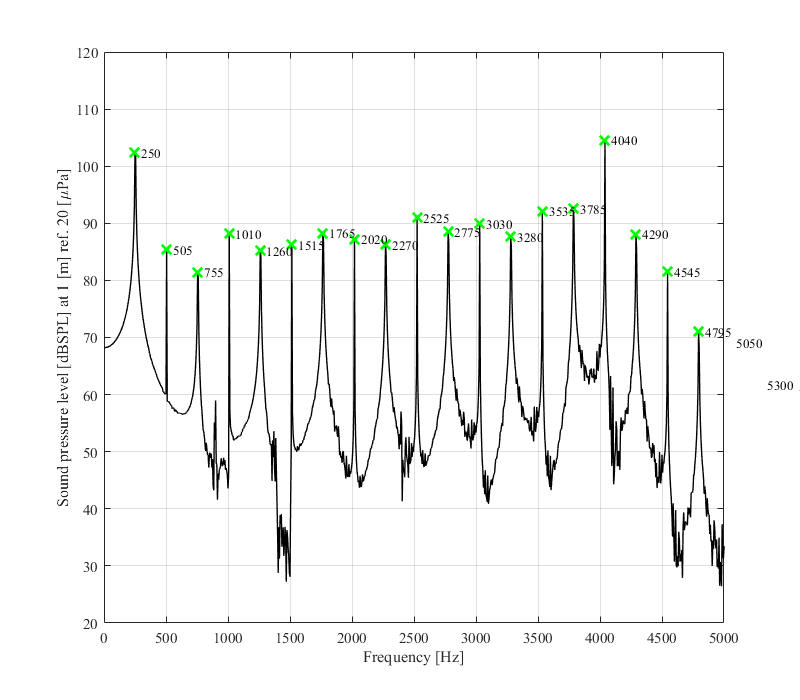

Elapsed time is 82.708321 seconds.


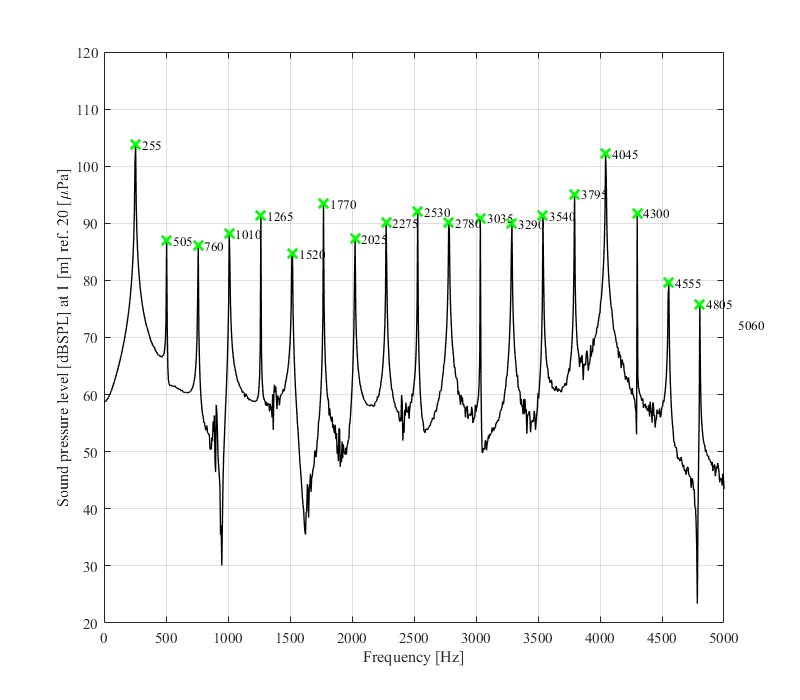

Elapsed time is 84.703411 seconds.


env.mdl = env.mdl_str;
env.in  = Simulink.SimulationInput(env.mdl);
env.in  = env.in.setModelParameter('StartTime','0','StopTime',num2str(env.stopt));

env.datestr= datestr(now, 'yymmddHHMM');
env.folder = strcat(proj.RootFolder,'/r_results/',env.datestr,'/');
env.folder_= strcat('r_results/',env.datestr,'/');
mkdir(env.folder);

for i = 1:length(env.sweep)
    tic
    env.mat_filename = strcat(env.folder_, env.mdl_str, '_', num2str(env.sweep(i)), 'V.mat');
    env.wav_filename = strcat(env.folder_, env.mdl_str, '_', num2str(env.sweep(i)), 'V.wav');

    env.in  = env.in.setBlockParameter(...
        [env.mdl '/To File'],               'FileName',env.mat_filename,...
        [env.mdl '/To Multimedia File'],    'FileName',env.wav_filename);
    env.in  = env.in.setVariable('el.ps.V',env.sweep(i));

    env.out = sim(env.in);

    env.all      = load([env.mdl_str num2str(env.sweep(i)) 'V.mat']);
    env.all.fs   = 1/env.all.p_rad(1,2);
    env.all.X    = env.all.p_rad(2,env.all.fs*env.stdyt+1:end)';
     
    [env.all.P1, env.all.f] = execFFT(env.all.X, env.all.fs);

    plotcompSPLFFT(env.all.f, 20*log10(abs(env.all.P1)/air.p_ref));

%     saveas(gcf, strcat(env.folder,env.mdl_str,'_',num2str(env.sweep(i)),'V.pdf'),'pdf');
    saveas(gcf, strcat(env.folder,env.mdl_str,'_',num2str(env.sweep(i)),'V.svg'),'svg');
    saveas(gcf, strcat(env.folder,env.mdl_str,'_',num2str(env.sweep(i)),'V.png'));
    toc
end

## **Operating voltage sweep - Parallel computing**

% clear env
% env.mdl_str = 'Bare_horn_Overall_time_dependent_3DOF_linear_driver_EMM';
% env.mdl = env.mdl_str;
% 
% el.ps.Vsweep    = 9:10;
% 
% for i = 1:length(el.ps.Vsweep)
%     env.in(i)   = Simulink.SimulationInput(env.mdl);
%     env.in(i)   = env.in(i).setModelParameter('StartTime','0','StopTime','0.3');
% 
%     env.in(i)  = env.in(i).setBlockParameter(...
%         [env.mdl '/To File'],               'FileName',[env.mdl_str num2str(el.ps.Vsweep(i)) 'V.mat'],...
%         [env.mdl '/To Multimedia File'],    'FileName',[env.mdl_str num2str(el.ps.Vsweep(i)) 'V.wav']);
%     env.in(i)  = env.in(i).setVariable('el.ps.V',el.ps.Vsweep(i));
% end
% 
% env.out = parsim(env.in,'ShowSimulationManager','off')


% for i = 9:15    % i for DC voltage parameter
% 
%     env.out = sim(env.in);
% 
%     ac.all      = load([env.mdl_str num2str(i) 'V.mat']);
%     ac.all.X    = ac.all.p_rad(2,200001:end)';
%     ac.all.fs   = 1/ac.all.p_rad(1,2);
%      
%     [ac.all.P1, ac.all.f] = execFFT(ac.all.X, ac.all.fs);
% 
%     plotcompSPLFFT(ac.all.f, 20*log10(abs(ac.all.P1)/air.p_ref));
% 
%     env.folder = strcat(proj.RootFolder,'/r_results/',datestr(now, 'yymmddHHMM'),'/');
%     mkdir(env.folder);
% 
%     saveas(gcf, strcat(env.folder,env.mdl_str,num2str(i),'V.pdf'),'pdf');
%     saveas(gcf, strcat(env.folder,env.mdl_str,num2str(i),'V.svg'),'svg');
%     saveas(gcf, strcat(env.folder,env.mdl_str,num2str(i),'V.png'));
% end